# 06 Quasi-Newton Methods

    The Hessian matrix $H$ is needed in computing Newton’s direction $p = -H^{-1}\nabla f$.

- What needed is the inverse multiplying a vector. 

- Approximate result, $B_k$ at each iteration, maybe good enough in use.

    **Quasi-Newton:** use gradient vector to approximate Hessian 

- DFP and BFGS updating formula

- SR1 (Symmetric Rank 1 update) method 

- Broyden class 

6.1 THE BFGS METHOD 

    **The secant formula**

- Suppose we have a symmetric positive definite (SPD) $B_k$ at current point $x_k$.

- Next point is $x_{k+1} = x_k + \alpha _kp_k$.

- The model at $x_{k+1}$ is $m_{k+1}(p) = f_{k+1} +\nabla f^T_{k+1}p + \frac{1}{2}p^TB_{k+1}p$

- Assume $\nabla m_{k+1}(-\alpha _kp_k) = \nabla f_{k+1} - \alpha _kB_{k+1}pk = \nabla f_k$ and 

- Let $s_k = x_{k+1} - x_k = \alpha _kp_k$ and  $y_{k}=\nabla f_{k+1}-\nabla f_k$

    Then we have **the secant formula** 


$$B_{k+1}s_{k}=y_{k}$$
 

- Requiring $B_{k+1}$ to be SPD, implies $s_k^TB_{k+1}s_k=s_k^Ty_{k}>0$.

    **DFP updating formula **(Davidon, Fletcher and Powell)

- The problem of approximating $B_{k+1}$ becomes


$$\min_{B}\|B-B_k\|, \quad \text{s.t. }\quad B^T=B, \text{ and } Bs_k=y_k$$


- With some special norm, the solution is

$B_{k+1} = \left(I - \rho _ky_ks^T_k\right)B_k\left(I - \rho _ks_ky^T_k\right) + \rho _ky_ky^T_k, \quad  \rho _k = 1/y^T_k s_k$    (DFP formula)

    Using the Sherman– Morrison–Woodbury formula (A.28), we can update $H_k=B_k^{-1}$

$H_{k+1} = H_k-\frac{H_ky_ky_k^TH_k}{y_k^TH_ky_k}+\frac{s_ks_k^T}{y_k^Ts_k}$     (DFP)

    **BFGS formula** (Broyden, Fletcher, Goldfarb, and Shanno)

- Let $H_k=B_k^{-1}$. Similar results can be obtained


$$\min_{H}\|H-H_k\|, \quad \text{s.t. }\quad H^T=H, \text{ and } Hs_k=y_k$$


- The solution is

$H_{k+1} = \left(I - \rho _ks_ky^T_k\right)H_k\left(I - \rho _ky_ks^T_k\right) + \rho _ks_ks^T_k, \quad  \rho _k = 1/y^T_k s_k$  (BFGS formula)

     Using the Sherman– Morrison–Woodbury formula (A.28), we can update $B_k$

$B_{k+1} = B_k-\frac{B_ks_ks_k^TB_k}{s_k^TB_ks_k}+\frac{y_ky_k^T}{y_k^Ts_k}$    (BFGS)

    How should we choose the initial approximation $H_0$?

- Finite difference or automatic differentiation (chap 8) 

- Using identity matrix or $(y_k^Ts_k/y_k^Ty_k)I$

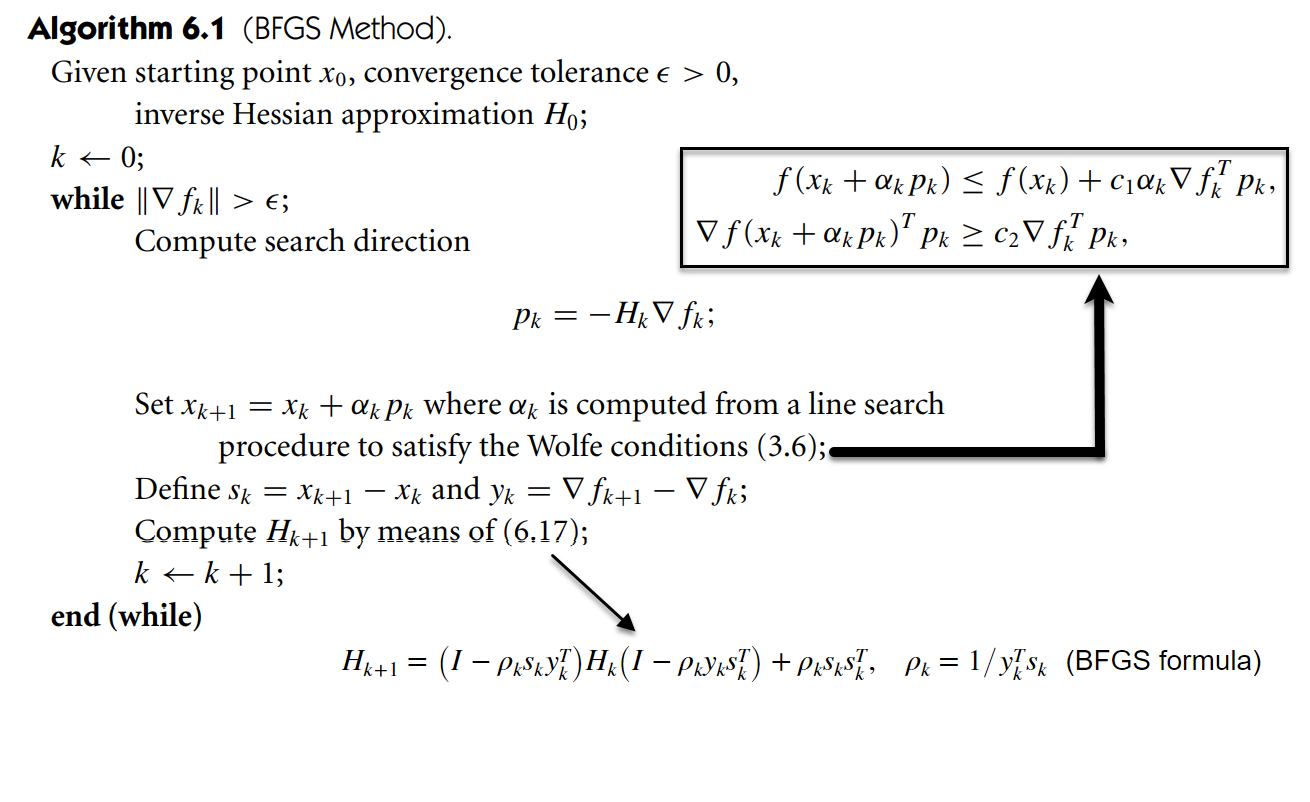

Remarks:

- Each iteration can be performed at a cost of $O(n^2)$ arithmetic operations (plus the cost of function and gradient evaluations); there are no $O(n^3)$ operations such as linear system solves or matrix–matrix operations. 

- The algorithm is robust, and its rate of convergence is **superlinear**, which is fast enough for most practical purposes. 

- Even though Newton’s method converges more rapidly (that is, quadratically), its cost per iteration usually is higher, because of its need for second derivatives and solution of a linear system.

#### Convergence of BFGS

**Theorem 6.5: **For any SDP $B_0$ and any $x_0$, if $f$ is twice continuously differentiable and the level set

                                            
$$L= \{x \in  \mathbb{R}^n |  f(x) \le  f (x_0)\}$$
 

is convex, and there exist positive constants $m$ and $M$ such that 

                                    $m\|z\|^2 \le  z^T \nabla^2f (x)z \le  M\|z\|^2$,  for all $z \in  \mathbb{R}^n$ and $x \in  L$.

then the sequence $\{x_k\}$ generated by **Algorithm 6.1** (with $\epsilon=0$) converges to the minimizer $x^\ast $ of $f.$

**SUPERLINEAR CONVERGENCE OF THE BFGS METHOD**

**Theorem 6.6.** Suppose that $f$ is twice continuously differentiable and that the iterates generated by the BFGS algorithm converge to a minimizer $x^\ast $ at which the Hessian matrix $G=\nabla^2f$ is Lipschitz continuous at $x^\ast $ , that is, 

                $\|G(x) - G(x^\ast )\| \le  L\|x - x^\ast \|$, for all $x$ near $x^\ast $ , where $L$ is a positive constant.

Suppose also that 

                        
$$\sum_{k=1}^{\infty} {\|x_k-x^*\|}< \infty$$


 Then $x_k$ converges to $x^\ast $ at a superlinear rate.

Rank-1 update:

A = [2 1 2 3;-1 -2 0 -2;0 1 -3 2;-2 1 -2 0];

A = A'*A;
y = [1 2 3 4]';
B = y*y'

B =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16


rank(B)

ans = 1

C= A + B

C =     10     4    11    12
     4    11     3    17
    11     3    26    12
    12    17    12    33


Example (BFGS)


$$\min_{(x_1,x_2)\in \mathbb{R}^2 }{\left(\frac{{x_1 }^2 }{8}-x_1 +\frac{{x_2 }^2 }{2}-x_2\right)}$$


clearvars;
% f(x) = 0.5x^T*Q*x - c^Tx
Q = [0.25 0;0 1]; c=[1;1]; x0=[0;0];

Q =     0.2500         0
         0    1.0000


f = @(x,y) 0.5*[x y]*Q*[x;y] - c'*[x;y];
g = @(x,y) Q*[x;y] - c;
%syms x_1 x_2 real;
%f(x_1,x_2)
% g(x_1,x_2);
epsilon = 1E-6;
H0 = eye(2);
g0 = g(x0(1),x0(2));
norm(g0)>epsilon;
p0 = -H0*g0;
alpha0 = -p0'*g0/(p0'*Q*p0); % exact value
x1 = x0+alpha0*p0;
g1 = g(x1(1),x1(2));
s0 = x1-x0; y0=g1-g0;
rho0 = 1/(y0'*s0);
H1 = (eye(2)-rho0*s0*y0')*H0*(eye(2)-rho0*y0*s0')+rho0*s0*s0';
g1 = g(x1(1),x1(2));
norm(g1)>epsilon

ans = logical
   1


% % check secant formula
% H1\s0 
% y0


p1 = -H1*g(x1(1), x1(2));
alpha1 = -p1'*g1/(p1'*Q*p1)

alpha1 = 2.5000

x2 = x1+alpha1*p1;
g2 = g(x2(1),x2(2));
s1 = x2-x1; y1=g2-g1;
rho1 = 1/(y1'*s1);
H2 = (eye(2)-rho1*s1*y1')*H1*(eye(2)-rho1*y1*s1')+rho1*s1*s1';
g2 = g(x2(1),x2(2));
norm(g2(1),g2(2))>epsilon;
x2;

